# Exercise 3

m = 30;
g = 9.81;
L = 2.5;
mu = 7;
w = sqrt(g/L);

u = @(t) m*L^2*cos(w*t);

[t,x] = ode45(@(t,x) swing(x,u(t),m,g,L,mu),[0 60],[0 0])

t =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


x =          0         0
    0.0000    0.0001
    0.0000    0.0001
    0.0000    0.0002
    0.0000    0.0002
    0.0000    0.0005
    0.0000    0.0007
    0.0000    0.0010
    0.0000    0.0012
    0.0000    0.0025


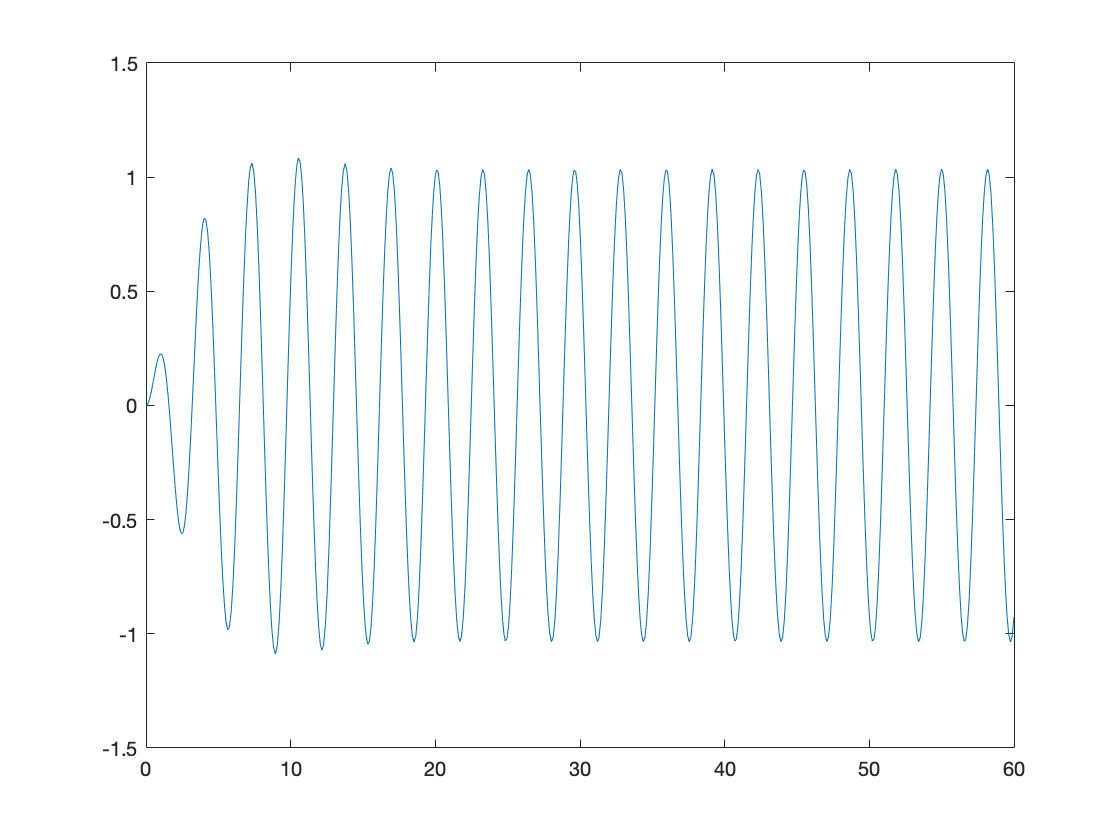


plot(t,x(:,1))

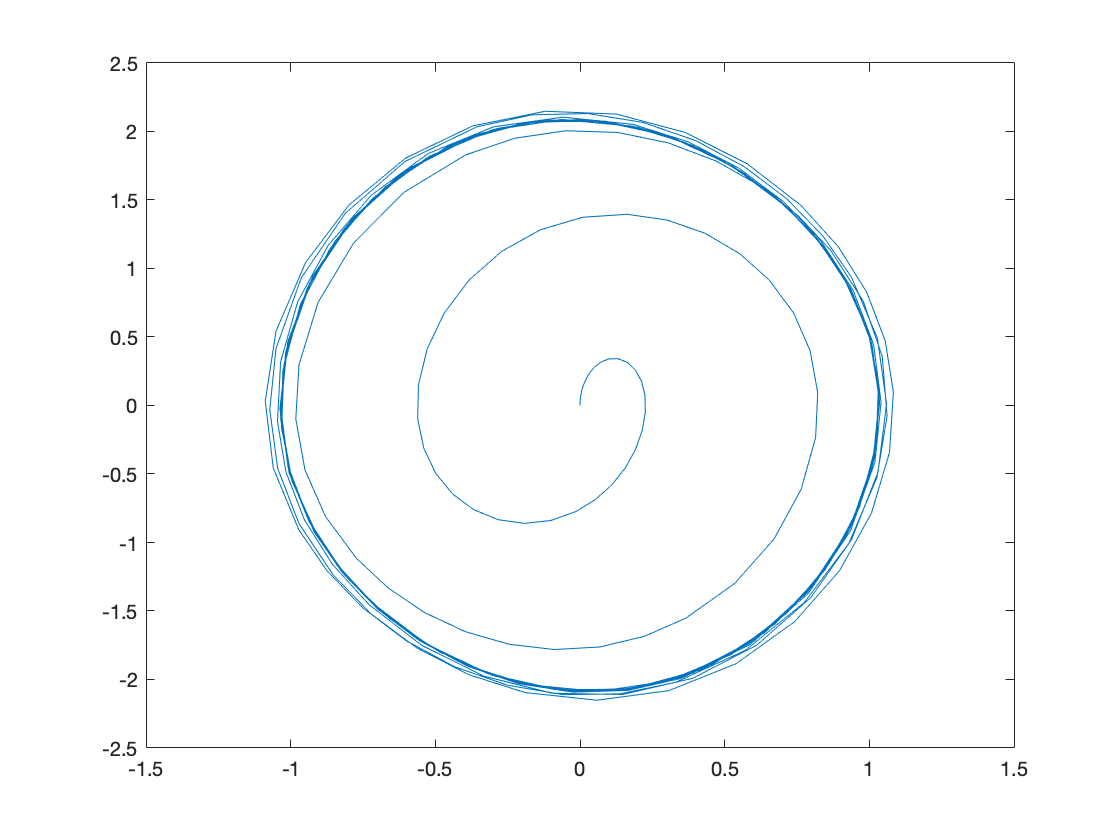

plot(x(:,1),x(:,2))

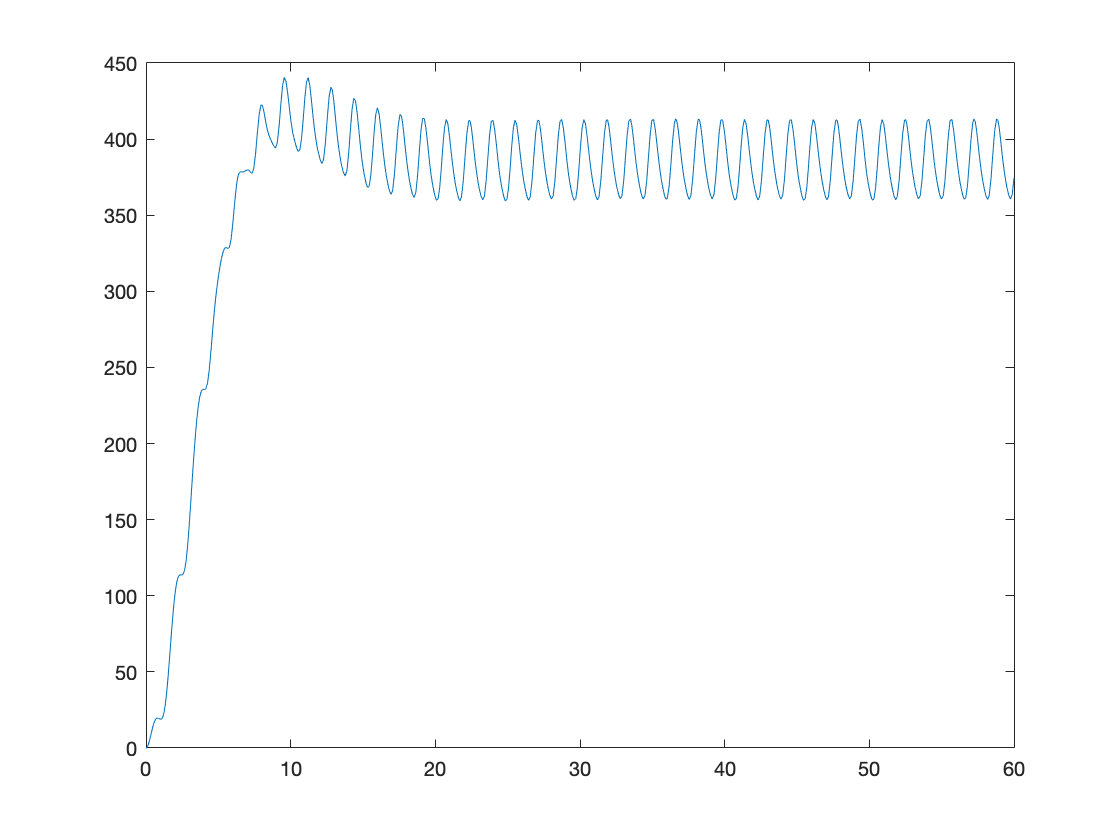

%comet(x(:,1),x(:,2),0.99)

E = m*g*L*(1-cos(x(:,1)))+1/2*m*L^2*x(:,2).^2;
plot(t,E)



[X,Y] = meshgrid(linspace(-2*pi,2*pi),linspace(-3,3,40))

X =    -6.2832   -6.1563   -6.0293   -5.9024   -5.7755   -5.6485   -5.5216   -5.3947   -5.2677   -5.1408   -5.0139   -4.8869   -4.7600   -4.6331   -4.5061   -4.3792   -4.2523   -4.1253   -3.9984   -3.8715   -3.7445   -3.6176   -3.4907   -3.3637   -3.2368   -3.1099   -2.9829   -2.8560   -2.7291   -2.6021   -2.4752   -2.3483   -2.2213   -2.0944   -1.9675   -1.8405   -1.7136   -1.5867   -1.4597   -1.3328   -1.2059   -1.0789   -0.9520   -0.8251   -0.6981   -0.5712   -0.4443   -0.3173   -0.1904   -0.0635
   -6.2832   -6.1563   -6.0293   -5.9024   -5.7755   -5.6485   -5.5216   -5.3947   -5.2677   -5.1408   -5.0139   -4.8869   -4.7600   -4.6331   -4.5061   -4.3792   -4.2523   -4.1253   -3.9984   -3.8715   -3.7445   -3.6176   -3.4907   -3.3637   -3.2368   -3.1099   -2.9829   -2.8560   -2.7291   -2.6021   -2.4752   -2.3483   -2.2213   -2.0944   -1.9675   -1.8405   -1.7136   -1.5867   -1.4597   -1.3328   -1.2059   -1.0789   -0.9520   -0.8251   -0.6981   -0.5712   -0.4443   -0.3173   -0.1904   -0

Y =    -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000
   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2.8462   -2

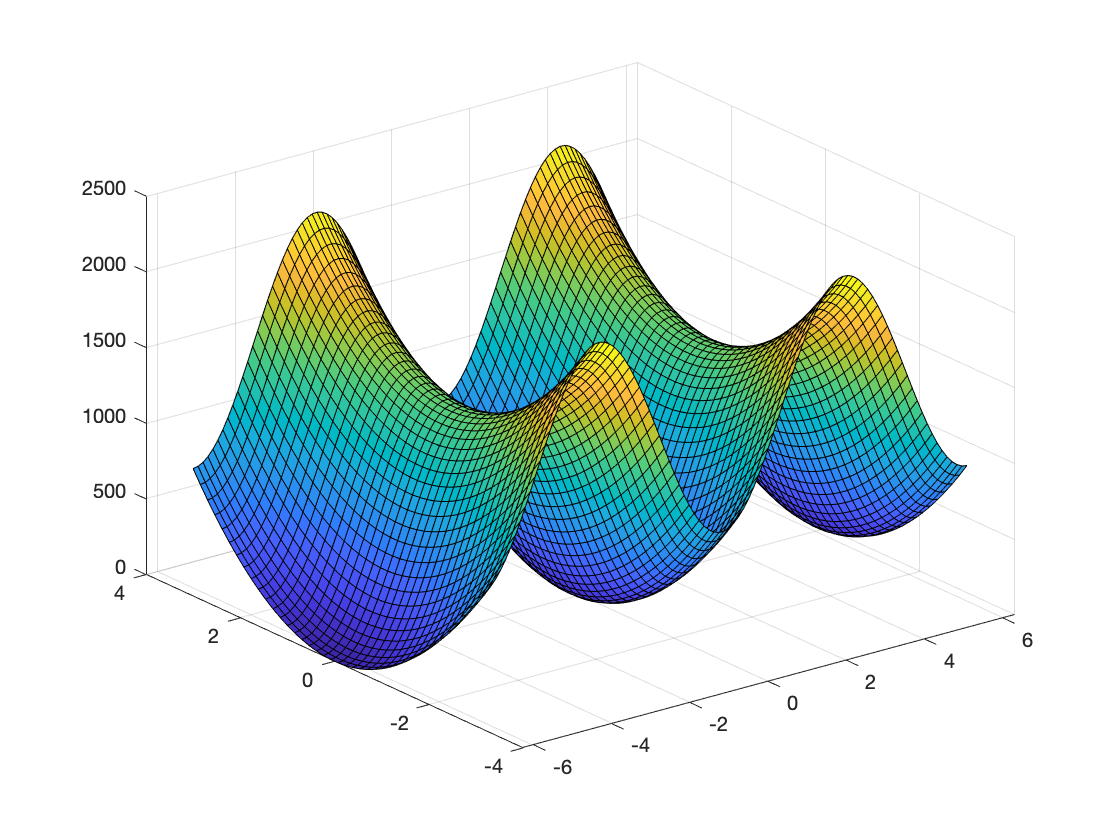

E = m*g*L*(1-cos(X))+1/2*m*L^2*Y.^2;
surf(X,Y,E)

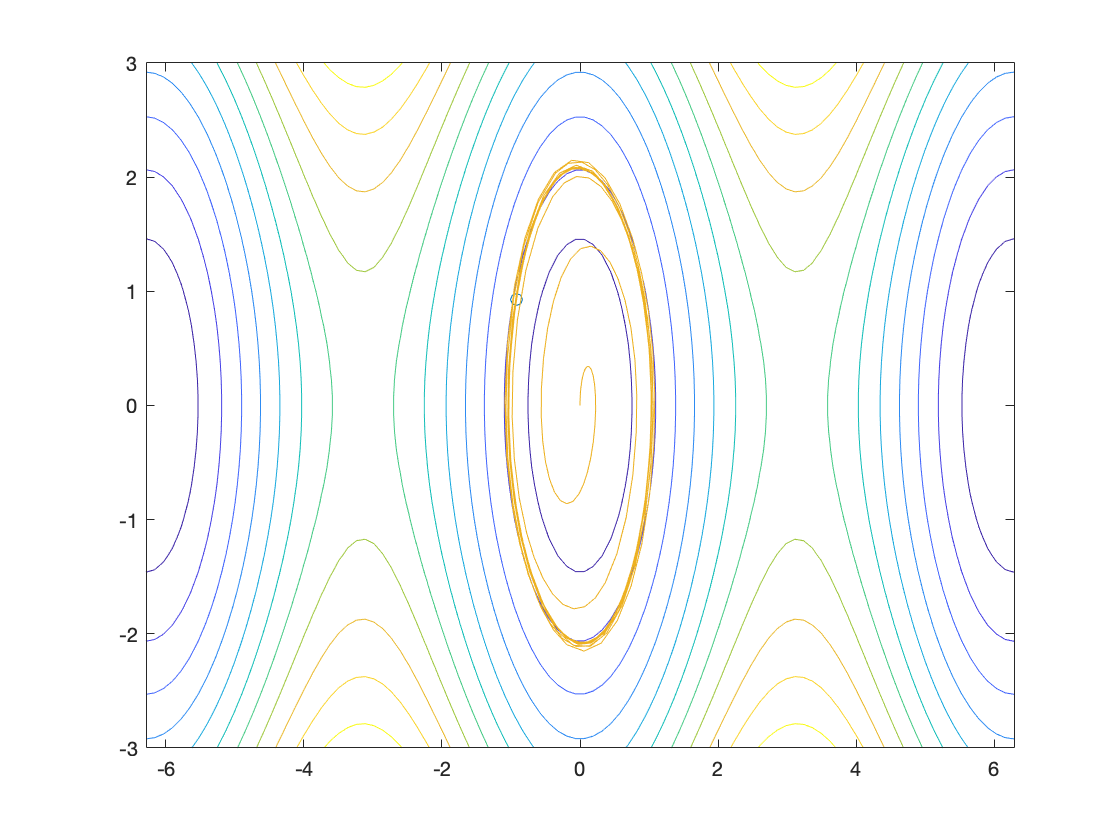

contour(X,Y,E)
hold on
comet(x(:,1),x(:,2),0.99)

function dx = swing(x,u,m,g,L,mu)

dx = [x(2)
     -g/L*sin(x(1))-mu/m*norm(x(2))*x(2)+1/(m*L^2)*u];
end